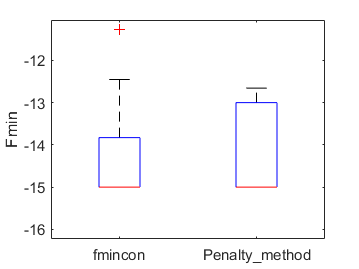

%优化结果对比
figure
boxplot([result_fmin_f(:,14),result_fmin_p(:,14)],"Labels",{'fmincon','Penalty_method'});
ylabel('Fmin');

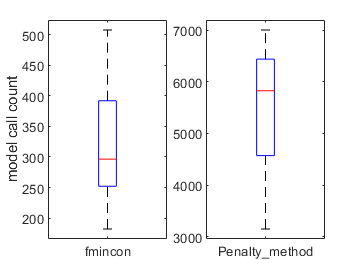


%模型调用次数
figure
subplot(1,2,1);
boxplot(result_fmin_f(:,15),"Labels",{'fmincon'});
ylabel('model call count');
subplot(1,2,2);
boxplot(result_fmin_p(:,15),"Labels",{'Penalty_method'});

data=[result_fmin_f(:,14:15),result_fmin_p(:,14:15)];
data_process=[min(data);mean(data);max(data);median(data)];